# ECG Prediction approach

Principal component regression

clear;
close all;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_ECG_lpf1Hz_DS25Hz_021916.mat');
% load('../data/CRB_dataset_ECG_lpf5Hz_DS25Hz_120516.mat');

figdir = '../figures';
datdir = '../data';


## Step 1. Creating Y: pain ratings

for i = 1:numel(D.Event_Level.data)
    y_int{i} = D.Event_Level.data{i}(:,12);
    y_unp{i} = -2*(D.Event_Level.data{i}(:,13)-50);
    xx{i} = [D.Event_Level.data{i}(:,11) D.Event_Level.data{i}(:,16) scale(D.Event_Level.data{i}(:,11),1).*scale(D.Event_Level.data{i}(:,16),1)];
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end

u_temp = unique(temp{1});
u_reg = unique(reg{1});

for subj = 1:numel(temp)
    for i = 1:numel(u_temp)
        for j = 1:numel(u_reg)
            dat_int{i,j}(subj,1) = nanmean(y_int{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
            dat_unp{i,j}(subj,1) = nanmean(y_unp{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
        end
    end
end

% Missing 39th subject's ECG data
for i = 1:numel(u_temp)
    for j = 1:numel(u_reg)
        dat_int{i,j}(39) = [];
        dat_unp{i,j}(39) = [];
    end
end


## Step 2. Creating X: ECG-IBI data (averaged over three trials)

for j = [1:38 40:numel(D.Continuous.data)] % 39th subj: missing data 
    
    scr = D.Continuous.data{j};
    
    ons = D.Event_Level.data{j}(:,5);
    
    for ii = 1:6
        for jj = 1:3
            signal{j}.cond{ii, jj} = [];
        end
    end
        
    for i = 1:numel(ons)
        
        temp_lev = D.Event_Level.data{j}(i,11)-43;
        reg_lev = D.Event_Level.data{j}(i,16)+2;
        a = round((ons(i)-3)*25);
        signal{j}.cond{temp_lev, reg_lev}(end+1,:) = scr(a:(a+(23*25))); 
    end
    
end


clear signal_m;
for i = 1:6
    for j = 1:3
        kk = 0;
        for subj = [1:38 40:numel(signal)]
            kk = kk + 1;
            signal_m{i,j}(kk,:) = mean(signal{subj}.cond{i,j} - repmat(mean(signal{subj}.cond{i,j}(:,1:75),2), 1, size(signal{subj}.cond{i,j},2)));
                                                     % subtracting the baseline, and then average
        end
    end
end

## Step 3. Running PCR 

3-1. Determining the number of components of the model

addpath('/Users/clinpsywoo/github/canlabrepo/CanlabCore/CanlabCore/External/lasso');

for i = 1:6
    for j = 1:3
        subjs{i,j} = (1:size(dat_int{i,j},1))';  % ready for leave-one-participant-out (LOPO) cross-validation
    end
end

dat.int = fmri_data;                                 % to use fmri_data.predict function, 
                                                 % put the data in fmri_data object
dat.int.Y = cat(1,dat_int{:,2});                     % add concatenated intensity ratings in dat.Y
dat.int.dat = cat(1,signal_m{:,2})';                 % add concatenated epoch data in dat.dat
                                                 % **For the training, we only used passive experience runs.**
dat.int.dat = dat.int.dat(76:575,:);                     % Stimulus-locked 20 seconds epoch 
whfolds = cat(1,subjs{:,2});                     % cross-validaion folds (LOPO CV)

dat.unp = dat.int;
dat.unp.Y = cat(1,dat_unp{:,2});  

savename = fullfile(datdir, 'ECG_prediction_dat_112816.mat');
save(savename, '-append', 'dat', 'whfolds', 'dat_int', 'dat_unp', 'signal_m');

clear rmse pred_outcome_r por_subj;
for i = 2:10
    if i == 2, disp('ECG predictive model for intensity ratings'); end
    [~, stats_int, ~] = predict(dat.int, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', i, 'verbose', 0);
    rmse.int(i-1) = stats_int.rmse;
    
    for j = unique(whfolds)'
        por_subj(j) = corr(stats_int.Y(whfolds==j), stats_int.yfit(whfolds==j));
    end
    
    pred_outcome_r.int(i-1) = mean(por_subj);
    fprintf('\n #component = %d, rmse = %1.4f, pred_outcome_r = %1.4f', i, stats_int.rmse, mean(por_subj));
end

ECG predictive model for intensity ratings



 #component = 2, rmse = 12.4100, pred_outcome_r = 0.5954


 #component = 3, rmse = 12.2368, pred_outcome_r = 0.5606


 #component = 4, rmse = 12.2527, pred_outcome_r = 0.5399


 #component = 5, rmse = 12.3077, pred_outcome_r = 0.5416


 #component = 6, rmse = 12.5637, pred_outcome_r = 0.5353


 #component = 7, rmse = 12.7443, pred_outcome_r = 0.5238


 #component = 8, rmse = 12.7361, pred_outcome_r = 0.5190


 #component = 9, rmse = 12.8680, pred_outcome_r = 0.5187


 #component = 10, rmse = 12.9008, pred_outcome_r = 0.5151


clear por_subj;
for i = 2:10
    if i == 2, disp('ECG predictive model for unpleasantness ratings'); end
    [~, stats_unp, ~] = predict(dat.unp, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', i, 'verbose', 0);
    
    rmse.unp(i-1) = stats_unp.rmse;
    
    for j = unique(whfolds)'
        por_subj(j) = corr(stats_unp.Y(whfolds==j), stats_unp.yfit(whfolds==j));
    end
    
    pred_outcome_r.unp(i-1) = mean(por_subj);
    fprintf('\n #component = %d, rmse = %1.4f, pred_outcome_r = %1.4f', i, stats_unp.rmse, mean(por_subj));
end

ECG predictive model for unpleasantness ratings



 #component = 2, rmse = 13.9014, pred_outcome_r = 0.5193


 #component = 3, rmse = 13.7435, pred_outcome_r = 0.5485


 #component = 4, rmse = 13.8098, pred_outcome_r = 0.5331


 #component = 5, rmse = 13.7444, pred_outcome_r = 0.5384


 #component = 6, rmse = 13.9120, pred_outcome_r = 0.5348


 #component = 7, rmse = 14.0649, pred_outcome_r = 0.5176


 #component = 8, rmse = 14.1232, pred_outcome_r = 0.5145


 #component = 9, rmse = 14.2681, pred_outcome_r = 0.5130


 #component = 10, rmse = 14.3396, pred_outcome_r = 0.5069

[~, ncomp_int] = max(-scale(rmse.int)+scale(pred_outcome_r.int));
[~, ncomp_unp] = max(-scale(rmse.unp)+scale(pred_outcome_r.unp));

fprintf('\n#component for intensity model = %d', ncomp_int+1);


#component for intensity model = 2

fprintf('\n#component for unpleasantness model = %d', ncomp_unp+1);


#component for unpleasantness model = 3

3-2. PCR model for intensity ratings with NCOMP = 2 & 3, bootstrapping 10000


[~, pcr_stats.int, ~] = predict(dat.int, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', 2, 'bootweights', 'bootsamples', 10000); % run it again

Cross-validated prediction with algorithm cv_pcr,  40 folds

Completed fit for all data in:   0 hours   0 min  0 secs 
Fold 1/40 done in:   0 hours   0 min  0 sec
Fold 2/40 done in:   0 hours   0 min  0 sec
Fold 3/40 done in:   0 hours   0 min  0 sec
Fold 4/40 done in:   0 hours   0 min  0 sec
Fold 5/40 done in:   0 hours   0 min  0 sec
Fold 6/40 done in:   0 hours   0 min  0 sec
Fold 7/40 done in:   0 hours   0 min  0 sec
Fold 8/40 done in:   0 hours   0 min  0 sec
Fold 9/40 done in:   0 hours   0 min  0 sec
Fold 10/40 done in:   0 hours   0 min  0 sec
Fold 11/40 done in:   0 hours   0 min  0 sec
Fold 12/40 done in:   0 hours   0 min  0 sec
Fold 13/40 done in:   0 hours   0 min  0 sec
Fold 14/40 done in:   0 hours   0 min  0 sec
Fold 15/40 done in:   0 hours   0 min  0 sec
Fold 16/40 done in:   0 hours   0 min  0 sec
Fold 17/40 done in:   0 hours   0 min  0 sec
Fold 18/40 done in:   0 hours   0 min  0 sec
Fold 19/40 done in:   0 hours   0 min  0 sec
Fold 20/40 done in:   0 hours   0 m

Bootstrapping weights, 10000 samples...Done in 341 sec
Correlation between bootstrapped mean weights and weights: 0.9979
Voxel weight Z-values range between -5.35 and 2.86
Returning weights and Z, p values in stats.WTS


[~, pcr_stats.unp, ~] = predict(dat.unp, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', 3, 'bootweights', 'bootsamples', 10000); % run it again

Cross-validated prediction with algorithm cv_pcr,  40 folds

Completed fit for all data in:   0 hours   0 min  0 secs 
Fold 1/40 done in:   0 hours   0 min  0 sec
Fold 2/40 done in:   0 hours   0 min  0 sec
Fold 3/40 done in:   0 hours   0 min  0 sec
Fold 4/40 done in:   0 hours   0 min  0 sec
Fold 5/40 done in:   0 hours   0 min  0 sec
Fold 6/40 done in:   0 hours   0 min  0 sec
Fold 7/40 done in:   0 hours   0 min  0 sec
Fold 8/40 done in:   0 hours   0 min  0 sec
Fold 9/40 done in:   0 hours   0 min  0 sec
Fold 10/40 done in:   0 hours   0 min  0 sec
Fold 11/40 done in:   0 hours   0 min  0 sec
Fold 12/40 done in:   0 hours   0 min  0 sec
Fold 13/40 done in:   0 hours   0 min  0 sec
Fold 14/40 done in:   0 hours   0 min  0 sec
Fold 15/40 done in:   0 hours   0 min  0 sec
Fold 16/40 done in:   0 hours   0 min  0 sec
Fold 17/40 done in:   0 hours   0 min  0 sec
Fold 18/40 done in:   0 hours   0 min  0 sec
Fold 19/40 done in:   0 hours   0 min  0 sec
Fold 20/40 done in:   0 hours   0 m

Bootstrapping weights, 10000 samples...Done in 431 sec
Correlation between bootstrapped mean weights and weights: 0.9925
Voxel weight Z-values range between -6.51 and 4.20
Returning weights and Z, p values in stats.WTS



save(fullfile(datdir, 'ECG_prediction_dat_112816.mat'), '-append', 'pcr_stats', 'pred_outcome_r', 'rmse');


3-4. See weights, significant time points

3-4-1. Plot for intensity 

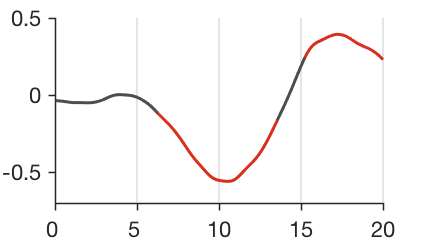

close all;

load(fullfile(datdir, 'ECG_prediction_dat_112816.mat'));

x = 1:500;
create_figure('PCR weights');

for i = (5:5:20)*25
    line([i i], [-1.2 1.2], 'col', [.8 .8 .8], 'linewidth', 1);
end

sig_idx = pcr_stats.int.WTS.wP<getFDR(pcr_stats.int.WTS.wP, .05);
% significant time points = [157:338 381:500]
idx{1} = 1:157;
idx{2} = 339:381;

idx{3} = 157:339;
idx{4} = 381:500;

for i = 1:2, plot(x(idx{i}), pcr_stats.int.other_output{1}(idx{i}), 'color', [.3 .3 .3], 'linewidth', 3); end
for i = 3:4, plot(x(idx{i}), pcr_stats.int.other_output{1}(idx{i}), 'color', [0.8431    0.1882    0.1216], 'linewidth', 3); end

set(gcf, 'position', [50   208   423   242]);
set(gca, 'ylim', [-0.7 .5], 'xlim', [0 500], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (0:5:24)*25, 'ytick', -1:.5:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25);
set(gca, 'fontSize', 22);
savename = fullfile(figdir, 'ECG_intensity_predictive_weights.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

3-4-2. Plot for unpleasantness

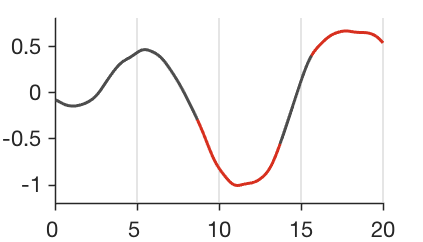

close all;

x = 1:500;
create_figure('PCR weights');

for i = (5:5:24)*25
    line([i i], [-1.2 1.2], 'col', [.8 .8 .8], 'linewidth', 1);
end

sig_idx = pcr_stats.unp.WTS.wP<getFDR(pcr_stats.unp.WTS.wP, .05);
% significant time points = [217:342 391:500]
idx{1} = 1:217;
idx{2} = 343:391;

idx{3} = 217:343;
idx{4} = 391:500;

for i=1:2, plot(x(idx{i}), pcr_stats.unp.other_output{1}(idx{i}), 'color', [.3 .3 .3], 'linewidth', 3); end
for i=3:4, plot(x(idx{i}), pcr_stats.unp.other_output{1}(idx{i}), 'color', [0.8431    0.1882    0.1216], 'linewidth', 3); end

set(gcf, 'position', [50   208   423   242]);
set(gca, 'ylim', [-1.2 .8], 'xlim', [0 500], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (0:5:24)*25, 'ytick', -1:.5:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25);
set(gca, 'fontSize', 22);

savename = fullfile(figdir, 'ECG_unpleasantness_predictive_weights.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


fprintf('\ncorrelation between intensity and unpleasantness weights r = %1.3f\n', corr(pcr_stats.int.other_output{1}, pcr_stats.unp.other_output{1}));


correlation between intensity and unpleasantness weights r = 0.855


## Step 4. Testing PCR models 

ecg = load(fullfile(datdir, 'ECG_prediction_dat_112816.mat'));

% Applying the model on regulation trials using leave-one-participant-out cross validation
for i = [1 3]
    for j = 1:6
        for subj = 1:size(ecg.signal_m{j,i},1)
            test_ecg_int{j,i}(subj,1) = ecg.signal_m{j,i}(subj,76:575)*ecg.pcr_stats.int.other_output_cv{subj,1} + ecg.pcr_stats.int.other_output_cv{subj,2};
            test_ecg_unp{j,i}(subj,1) = ecg.signal_m{j,i}(subj,76:575)*ecg.pcr_stats.unp.other_output_cv{subj,1} + ecg.pcr_stats.unp.other_output_cv{subj,2};
        end
    end
end

temp_int = reshape(ecg.pcr_stats.int.yfit, 40, 6);
temp_unp = reshape(ecg.pcr_stats.unp.yfit, 40, 6);

for j = 1:6
    test_ecg_int{j,2} = temp_int(:,j);
    test_ecg_unp{j,2} = temp_unp(:,j);
end

% scatter plot
y_int = [cat(2,ecg.dat_int{:,1}) cat(2,ecg.dat_int{:,3})];
yfit_int = [cat(2,test_ecg_int{:,1}) cat(2,test_ecg_int{:,3})];

y_unp = [cat(2,ecg.dat_unp{:,1}) cat(2,ecg.dat_unp{:,3})];
yfit_unp = [cat(2,test_ecg_int{:,1}) cat(2,test_ecg_int{:,3})];

save(fullfile(datdir, 'ECG_prediction_dat_112816.mat'), '-append', 'test_ecg_*')


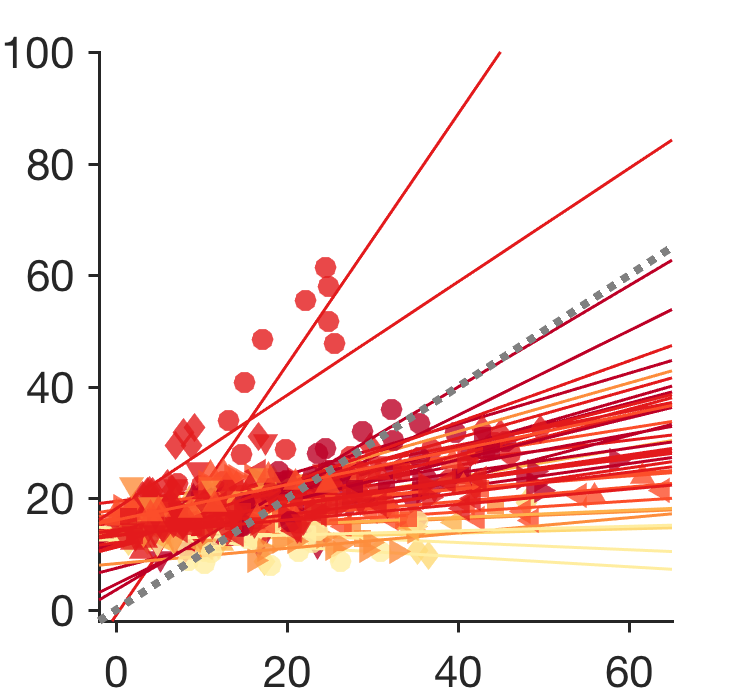

colors = [255,237,160
254,217,118
254,178,76
253,141,60
252,78,42
227,26,28
189,0,38]./255;

xlim = [-2 65];
create_figure('predicted');

clear test_por;
for i = 1:size(y_int,1)
    hold on;
    x = y_int(i,:);
    y = yfit_int(i,:);
    b = glmfit(x,y);
    test_por(i) = corr(x',y');
end

dif = 1/size(colors,1);

k = zeros(size(test_por));
for i = 1:size(colors,1)
    idx = test_por <= (dif*i+.0001) & test_por >= (dif*(i-1));
    k(idx) = i;
end

k(k==0) = 1;

marker_shapes = repmat('osd^v><', 1, 40);

for i = 1:size(y_int,1)
    hold on;
    x = y_int(i,:);
    y = yfit_int(i,:);
    b = glmfit(x,y);
    line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', colors(k(i),:)); % cmap(round(i*1.5),:));
    scatter(x, y, 120, colors(k(i),:), 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
end

set(gcf, 'position', [360   349   371   349]);
set(gca, 'tickdir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xlim', xlim, 'ylim', [-2 100], 'fontsize', 22);

line(xlim, xlim, 'linewidth', 4, 'linestyle', ':', 'color', [.5 .5 .5]);

savename = fullfile(figdir, 'ECG_actual_predicted_outcomes.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

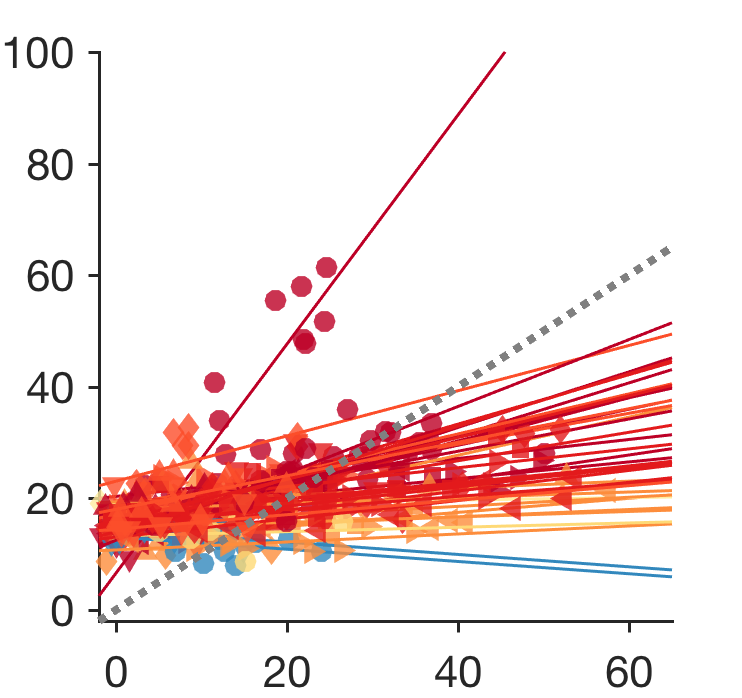


create_figure('predicted_unp');
dif = 1/size(colors,1);

clear test_por_unp;
for i = 1:size(y_unp,1)
    hold on;
    x = y_unp(i,:);
    y = yfit_unp(i,:);
    b = glmfit(x,y);
    test_por_unp(i) = corr(x',y');
end

k = zeros(size(test_por_unp));
for i = 1:size(colors,1)
    idx = test_por_unp <= (dif*i+.0001) & test_por_unp >= dif*(i-1);
    k(idx) = i;
end

marker_shapes = repmat('osd^v><', 1, 40);

for i = 1:size(y_unp,1)
    hold on;
    x = y_unp(i,:);
    y = yfit_unp(i,:);
    b = glmfit(x,y);
    try
        line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', colors(k(i),:)); % cmap(round(i*1.5),:));
        scatter(x, y, 120, colors(k(i),:), 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
    catch
        line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', [0.1961    0.5333    0.7412]); % cmap(round(i*1.5),:));
        scatter(x, y, 120, [0.1961    0.5333    0.7412], 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
    end
    
end

line(xlim, xlim, 'linewidth', 4, 'linestyle', ':', 'color', [.5 .5 .5]);

set(gcf, 'position', [360   349   371   349]);
set(gca, 'tickdir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xlim', xlim, 'ylim', [-2 100], 'fontsize', 22);

savename = fullfile(figdir, 'ECG_actual_predicted_outcomes_unpleasant.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);




fprintf('\nTest results: mean prediction_outcome_r for intensity = %1.3f', mean(test_por));


Test results: mean prediction_outcome_r for intensity = 0.666

fprintf('\nTest results: mean prediction_outcome_r for unpleasantness = %1.3f', mean(test_por_unp));


Test results: mean prediction_outcome_r for unpleasantness = 0.650

## Step 5. Test the effects of temperature and regulation on ECG pattern response

5-1. Intensity

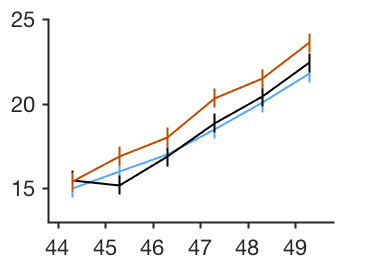

load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');
load(fullfile(datdir, 'ECG_prediction_dat_112816.mat'));

clear reg_all reg temp;

for i = 1:numel(D.Event_Level.data)
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end

% dosavefig = false; % save figure in matlab 2014 (was written in 2014 previously)
figdir = '../figures';

reg_all{1} = cat(2,test_ecg_int{:,1})';
reg_all{2} = cat(2,test_ecg_int{:,2})';
reg_all{3} = cat(2,test_ecg_int{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 15:5:25, 'ylim', [13 25]);

set(gca, 'fontsize', 22);

%figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
savename = fullfile(figdir, 'test_ecg_int.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

5-2. Unpleasantness

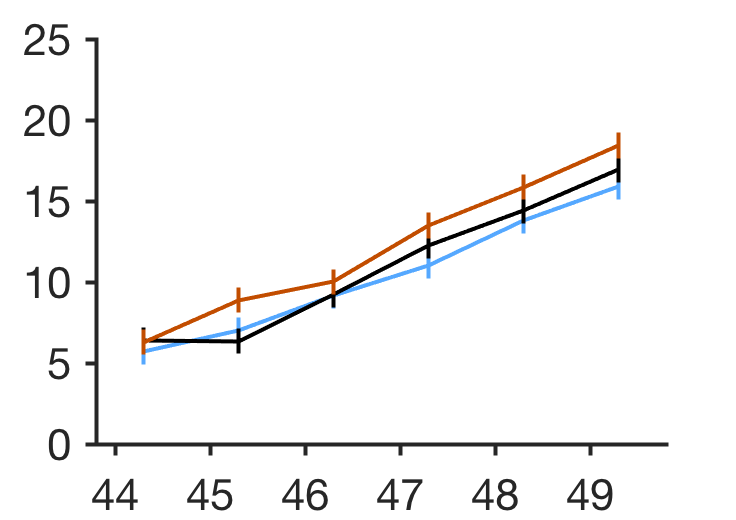


reg_all{1} = cat(2,test_ecg_unp{:,1})';
reg_all{2} = cat(2,test_ecg_unp{:,2})';
reg_all{3} = cat(2,test_ecg_unp{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
    0         0         0
    0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 0:5:25, 'ylim', [0 22]);

set(gca, 'fontsize', 22);

%figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
savename = fullfile(figdir, 'test_ecg_unp.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

5-3. multilevel GLM analysis for ECG intensity 

clear yy_int yy_unp xx;

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];
for i = 1:size(test_ecg_int{1},1)
    xx{i} = [temp reg scale(temp,1).*scale(reg,1)];
    
    kk = 0;
    for k = 1:3
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_ecg_int{j,k}(i);
            yy_unp{i}(kk,1) = test_ecg_unp{j,k}(i);
        end
    end
end
glm_ecg_int = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.65 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	13.29	1.49	0.62	0.14	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	13.29	1.50	0.62	0.13	
STE	0.30	0.23	0.15	0.06	
t	43.10	6.48	4.19	2.18	
Z	3.06	4.85	3.91	2.16	
p	0.0011	0.0000	0.0000	0.0154	

________________________________________


ECG unpleasantness


glm_ecg_unp = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.64 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	3.25	2.27	0.87	0.17	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	3.26	2.27	0.87	0.17	
STE	0.39	0.29	0.23	0.11	
t	8.21	7.65	3.76	1.53	
Z	3.26	4.13	4.09	1.38	
p	0.0006	0.0000	0.0000	0.0837	

________________________________________


5-4. Plotting GLM results

Intensity

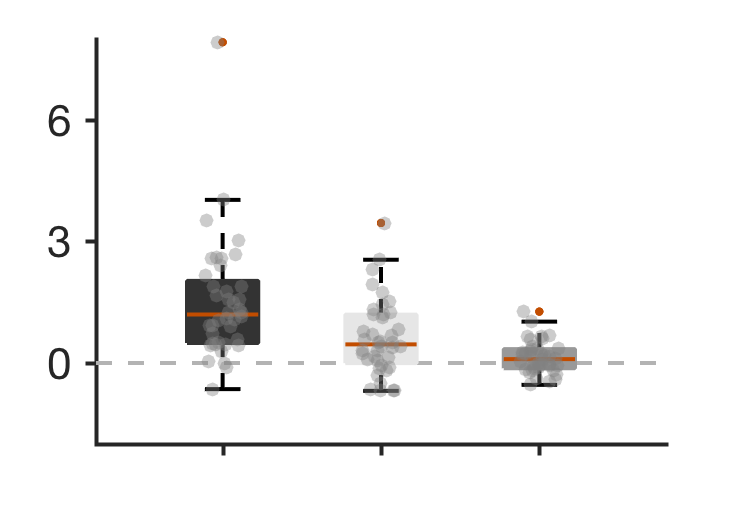

load(fullfile(datdir, 'ECG_prediction_dat_112816.mat'));

dosavefig = true;
edgecolor = 'k';
facecolor = [.2 .2 .2;
    .9 .9 .9;
    .6 .6 .6];

close all;
boxplot_wani_2016(glm_ecg_int.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position', [360   438   368   260]);
set(gca, 'fontsize', 22, 'linewidth', 2, 'ticklength', [.02 .02], 'ylim', [-2 8], 'ytick', [0:3:9]);

scatter(reshape(repmat(1:3, 40, 1), 40*3,1)+scale(rand(40*3,1))/15, ...
    reshape(glm_ecg_int.first_level.beta(2:4,:)', 40*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

savename = fullfile(figdir, 'test_ecg_int_glm_box.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

Unpleasantness

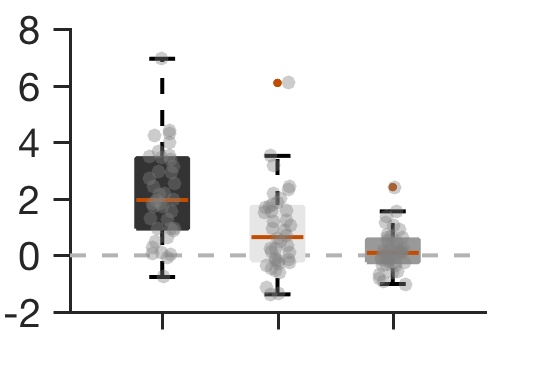


close all;
boxplot_wani_2016(glm_ecg_unp.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04], 'ylim', [-2 8]);

h = scatter(reshape(repmat(1:3, 40, 1), 40*3,1)+scale(rand(40*3,1))/15, ...
    reshape(glm_ecg_unp.first_level.beta(2:4,:)', 40*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

savename = fullfile(figdir, 'test_ecg_unp_glm_box.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

5-5. Test passive vs. down

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];

%% passive vs. down

clear yy_int yy_unp;

for i = 1:size(test_ecg_int{1},1)
    xx{i} = [temp(1:12) scale(reg(1:12),1) scale(temp(1:12),1).*scale(reg(1:12),1)];
    
    kk = 0;
    for k = 1:2
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_ecg_int{j,k}(i);
            yy_unp{i}(kk,1) = test_ecg_unp{j,k}(i);
        end
    end
end

glm_ecg_int = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.75 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	13.13	1.43	0.15	0.14	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	13.14	1.43	0.14	0.14	
STE	0.32	0.22	0.30	0.13	
t	40.26	6.24	0.46	1.02	
Z	3.24	4.45	0.52	0.65	
p	0.0006	0.0000	0.6968	0.2592	

________________________________________



glm_ecg_unp = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.78 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	3.04	2.19	0.50	0.19	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	3.04	2.19	0.50	0.20	
STE	0.43	0.29	0.45	0.20	
t	6.93	7.44	1.10	0.98	
Z	3.37	3.90	0.58	0.60	
p	0.0004	0.0000	0.2800	0.2741	

________________________________________


5-6. Test up vs. passive

clear yy_int yy_unp;

for i = 1:size(test_ecg_int{1},1)
    xx{i} = [temp(7:18) scale(reg(7:18),1) scale(temp(7:18),1).*scale(reg(7:18),1)];
    
    kk = 0;
    for k = 2:3
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_ecg_int{j,k}(i);
            yy_unp{i}(kk,1) = test_ecg_unp{j,k}(i);
        end
    end
end

glm_scr_int = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.57 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	13.28	1.56	1.09	0.13	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	13.28	1.57	1.09	0.13	
STE	0.37	0.24	0.31	0.12	
t	35.21	6.39	3.53	1.09	
Z	3.00	4.86	3.38	0.59	
p	0.0014	0.0000	0.0004	0.2768	

________________________________________



glm_scr_unp = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  40, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.75 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	3.32	2.36	1.23	0.14	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	3.32	2.36	1.24	0.14	
STE	0.48	0.31	0.43	0.20	
t	6.89	7.49	2.82	0.70	
Z	3.25	4.11	2.82	0.08	
p	0.0006	0.0000	0.0024	0.4676	

________________________________________
